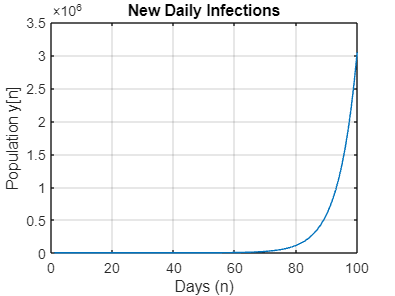

% Problem 2
% Transfer function
numerator = 1;
denominator = -1.*[-1, .1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1];
ts = 0.1;
sys = tf(numerator,denominator,ts,'Variable','z^-1');

% Part (1)
H =1/( 1 - 0.1*z^-1 - 0.15*z^-2 - 0.25*z^-3 - 0.26*z^-4 - 0.34*z^-5 - 0.42*z^-6 - 0.25*z^-7 - 0.2*z^-8 - 0.15*z^-9 - 0.1*z^-10 - 0.1*z^-11 - 0.1*z^-12);
ySol1 = iztrans(H,z,n); % Time domain equation
ySol1 = simplify(ySol1); 
nValues1 = 1:100;
ySolValues1 = subs(ySol1,n,nValues1);
ySolValues1 = double(ySolValues1);
ySolValues1 = real(ySolValues1);
figure;
plot(nValues1,ySolValues1)
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on


Integrator1 = filter(1,[1 -1],ySolValues1);
Total_infections1 = Integrator1(end) % Total infections in 100 days

Total_infections1 = 2.0044e+07


% Part(2)
Days = nValues1(ySolValues1 == ySolValues1(94))

Days = 94